% construct similarity matrix
n_res=size(msa_aa,2)

n_res = 369

n_seq=size(msa_aa,1)

n_seq = 2179


similarity_matrix = zeros(n_seq,n_seq);

for i=1:n_seq
    for j=1:n_seq
        similarity = sum(msa_aa(i,:)==msa_aa(j,:))/ n_res;
        similarity_matrix(i,j) = similarity;
    end
end

% PCA
[coeff,score,latent] = pca(zscore(similarity_matrix));
PC1 = score(:,1);
PC2 = score(:,2);

% find outliers
median_1 = median(PC1);
mad_1 = median(abs(PC1-median_1));
outliers_1_index = find (abs(PC1-median_1) > 3*mad_1);


median_2 = median(PC2);
mad_2 = median(abs(PC2-median_2));
outliers_2_index = find (abs(PC2-median_2) > 3*mad_2);


outliers = unique(cat(1,outliers_1_index,outliers_2_index));
length(outliers)

ans = 669

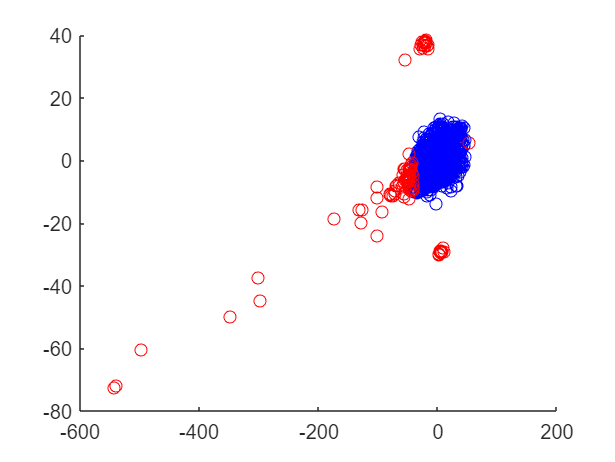



% plot
scatter(PC1,PC2,'blue')
hold on
scatter(PC1(outliers_1_index),PC2(outliers_1_index),'red')
scatter(PC1(outliers_2_index),PC2(outliers_2_index),'red')